no_of_terms = input('请输入递归次数 ');
Leibniz_error = zeros(no_of_terms, 1);
Euler_error = zeros(no_of_terms, 1);

% Leibniz
sum1 = 0;
for k = 0:(no_of_terms-1)
    sum1 = sum1 + 1.0/((4*k + 1)*(4*k + 3));
    Leibniz_error(k+1) = pi - 8*sum1;
end
sum1 = 8*sum1;
final_Leibniz_error = abs(pi - sum1);
fprintf('莱布尼兹误差: %g \n', final_Leibniz_error)

莱布尼兹误差: 0.00499997 



% Euler
sum2 = 0;
for k = 1:no_of_terms      % Note index range
    sum2 = sum2 + 1.0/k^2;
    Euler_error(k) = pi - sqrt(6*sum2);
end
sum2 = 6*sum2;
sum2 = sqrt(sum2);
final_Euler_error = abs(pi - sum2);
fprintf('欧拉误差: %g \n', final_Euler_error)

欧拉误差: 0.00951612 


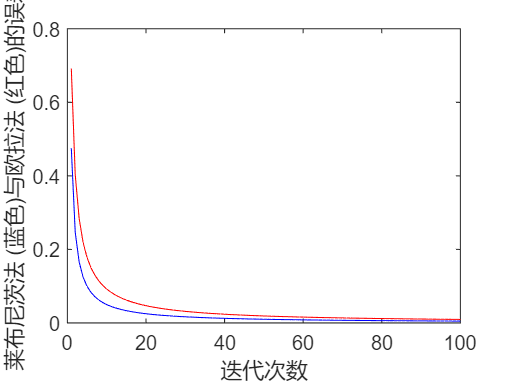


figure(); plot([1:no_of_terms], Leibniz_error, 'b-',...
               [1:no_of_terms], Euler_error, 'r-');
xlabel('迭代次数');
ylabel('莱布尼茨法 (蓝色)与欧拉法 (红色)的误差');